# **Dry single BbarBrick element with pressure dependent material**

opsMat = OpenSeesMatlab();
ops = opsMat.opensees;

%% dry single BbarBrick element with pressure dependent material
% subjected to 1D sinusoidal base shaking

ops.wipe();

friction = 31.40;              % friction angle
phaseTransform = 26.50;        % phase transformation angle
E1 = 93178.4;                  % Young's modulus
poisson1 = 0.40;
G1 = E1 / (2 * (1 + poisson1));
B1 = E1 / (3 * (1 - 2 * poisson1));
gamma = 0.600;                 % Newmark integration parameter

dt = 0.01;                     % time step for analysis
numSteps = 1600;               % number of time steps
rhoS = 2.00;                   % saturated mass density
rhoF = 0.00;                   % fluid mass density
densityMult = 1.0;             % density multiplier

Bfluid = 2.2e6;                % fluid shear modulus
fluid1 = 1;                    % fluid material tag
solid1 = 10;                   % solid material tag

accMul = 4;                    % acceleration multiplier
piVal = 3.1415926535;
inclination = 0;

massProportionalDamping = 0.0;
InitStiffnessProportionalDamping = 0.001;

bUnitWeightX = (rhoS - 0.0) * 9.81 * sin(inclination / 180.0 * piVal) * densityMult;
bUnitWeightY = 0.0;
bUnitWeightZ = -(rhoS - rhoF) * 9.81 * cos(inclination / 180.0 * piVal);

ndm = 3;

ops.model('BasicBuilder', '-ndm', ndm, '-ndf', ndm);

ops.nDMaterial('PressureDependMultiYield', ...
    solid1, ndm, rhoS * densityMult, G1, B1, ...
    friction, 0.1, 80, 0.5, ...
    phaseTransform, 0.17, 0.4, 10, 10, 0.015, 1.0);

ops.node(1, 0.00000, 0.0000, 0.00000);
ops.node(2, 0.00000, 0.0000, 1.00000);
ops.node(3, 0.00000, 1.0000, 0.00000);
ops.node(4, 0.00000, 1.0000, 1.00000);
ops.node(5, 1.00000, 0.0000, 0.00000);
ops.node(6, 1.00000, 0.0000, 1.00000);
ops.node(7, 1.00000, 1.0000, 0.00000);
ops.node(8, 1.00000, 1.0000, 1.00000);

ops.element('bbarBrick', ...
    1, 1, 5, 7, 3, 2, 6, 8, 4, ...
    solid1, bUnitWeightX, bUnitWeightY, bUnitWeightZ);

ops.updateMaterialStage('-material', solid1, '-stage', 0);

ops.fix(1, 1, 1, 1, 0, 0, 0);
ops.fix(2, 0, 1, 0, 0, 0, 0);
ops.fix(3, 1, 1, 1, 0, 0, 0);
ops.fix(4, 0, 1, 0, 0, 0, 0);
ops.fix(5, 1, 1, 1, 0, 0, 0);
ops.fix(6, 0, 1, 0, 0, 0, 0);
ops.fix(7, 1, 1, 1, 0, 0, 0);
ops.fix(8, 0, 1, 0, 0, 0, 0);

% equalDOF: tied nodes around
ops.equalDOF(2, 4, 1, 3);
ops.equalDOF(2, 6, 1, 3);
ops.equalDOF(2, 8, 1, 3);

nodeList = 1:8;
elementList = 1:1;

%% GRAVITY APPLICATION (elastic behavior)
ops.system("ProfileSPD");
ops.test('NormDispIncr', 1.0e-10, 25, 2);
ops.constraints('Transformation');
ops.integrator('LoadControl', 1, 1, 1, 1);
ops.algorithm('Newton');
ops.numberer('RCM');
ops.analysis('Static');
ops.analyze(2);

[OpenSees] CTestNormDispIncr::test() - iteration: 2 current Norm: 1.6125e-20 (max: 1e-10, Norm deltaR: 1.16573e-15)
[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 5.83836e-21 (max: 1e-10, Norm deltaR: 3.88578e-16)



% switch the material to plastic
ops.updateMaterialStage('-material', solid1, '-stage', 1);
% ops.updateMaterials('-material', solid1, 'bulkModulus', G1 * 2 / 3);

ops.analyze(2);

[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 7.62496e-21 (max: 1e-10, Norm deltaR: 7.59948e-14)
[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 1.31009e-18 (max: 1e-10, Norm deltaR: 6.71685e-15)


ops.setTime(0.0);   % reset time
ops.wipeAnalysis();
%% create recorders
ops.recorder("Node", ...
    '-file', 'output_data/allNodesDisp.out', ...
    '-time', ...
    '-node', nodeList,...
    '-dof', 1, 2, 3, ...
    '-dT', 0.01, ...
    'disp');

ops.recorder('Node', ...
    '-file', 'output_data/allNodesAcce.out', ...
    '-time', ...
    '-node', nodeList, ...
    '-dof', 1, 2, 3, ...
    '-dT', 0.01, ...
    'accel');

ops.recorder("Element", ...
    '-ele', elementList, ...
    '-time', ...
    '-file', 'output_data/stress1.out', ...
    '-dT', 0.01, ...
    "material", 1, "stress");

ops.recorder('Element', ...
    '-ele', elementList, ...
    '-time', ...
    '-file', 'output_data/strain1.out', ...
    '-dT', 0.01, ...
    'material', 1, 'strain');

ops.recorder('Element', ...
    '-ele', elementList, ...
    '-time', ...
    '-file', 'output_data/stress5.out', ...
    '-dT', 0.01, ...
    'material', 5, 'stress');

ops.recorder('Element', ...
    '-ele', elementList, ...
    '-time', ...
    '-file', 'output_data/strain5.out', ...
    '-dT', 0.01, ...
    'material', 5, 'strain');

ops.recorder('Element', ...
    '-ele', elementList, ...
    '-file', 'output_data/backbone.out', ...
    '-dT', 1000, ...
    'material', 1, 'backbone', 80, 100, 200, 300);



%% create dynamic time history analysis

ops.timeSeries('Sine', 1, 0.0, 10.0, 1.0, '-factor', accMul)
ops.pattern('UniformExcitation', 1, 1, '-accel', 1)

ops.rayleigh(massProportionalDamping, 0.0, InitStiffnessProportionalDamping, 0.0);

beta = (gamma + 0.5)^2 / 4;
ops.integrator('Newmark', gamma, beta);

ops.constraints('Penalty', 1.0e18, 1.0e18);
ops.test('NormDispIncr', 1.0e-10, 25, 0);
ops.algorithm('ModifiedNewton');
ops.system('ProfileSPD');
ops.numberer('Plain');
ops.analysis('VariableTransient');

%% perform the analysis and record time used
startT = tic;
ops.analyze(numSteps, dt, dt / 64, dt, 15);

[OpenSees] 80
[OpenSees] 100
[OpenSees] 200
[OpenSees] 300


ops.wipe();
elapsedTime = toc(startT);

fprintf('Execution time: %.6f seconds.\n', elapsedTime);

Execution time: 0.435562 seconds.


a1=load('output_data/allNodesAcce.out');
d1=load('output_data/allNodesDisp.out');
s1=load('output_data/stress1.out');
e1=load('output_data/strain1.out');
s5=load('output_data/stress5.out');
e5=load('output_data/strain5.out');

fs=[0.5, 0.2, 4, 6];
accMul = 4;

%integration point 1 p-q
po=(s1(:,2)+s1(:,3)+s1(:,4))/3;
for i=1:size(s1,1)
    qo(i)=(s1(i,2)-s1(i,3))^2 + (s1(i,3)-s1(i,4))^2 +(s1(i,2)-s1(i,4))^2 + 6.0* s1(i,5)^2 + 6.0* s1(i,6)^2 + 6.0* s1(i,7)^2;
    qo(i)=sign(s1(i,7))*1/3.0*qo(i)^0.5;
end

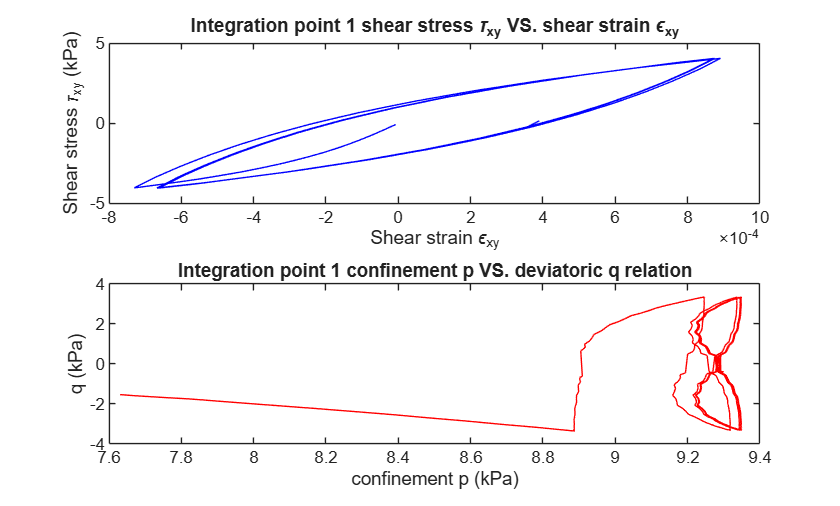


figure(1); clf;
%integration point 1 stress-strain
subplot(2,1,1), plot(e1(:,7),s1(:,7),'b');
title ('Integration point 1 shear stress \tau_x_y VS. shear strain \epsilon_x_y');
xlabel('Shear strain \epsilon_x_y');
ylabel('Shear stress \tau_x_y (kPa)');

subplot(2,1,2), plot(-po,qo,'r');
title ('Integration point 1 confinement p VS. deviatoric q relation');
xlabel('confinement p (kPa)');
ylabel('q (kPa)');

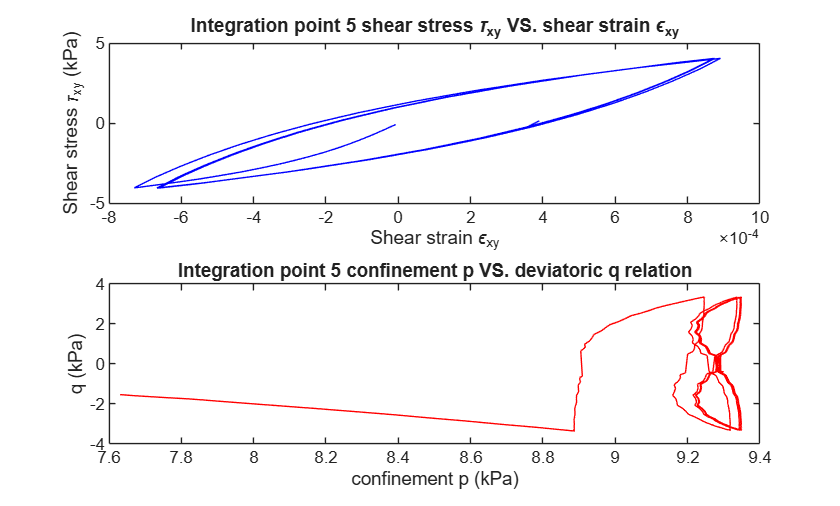

%integration point 5 p-q
po=(s5(:,2)+s5(:,3)+s5(:,4))/3;
for i=1:size(s5,1)
    qo(i)=(s5(i,2)-s5(i,3))^2 + (s5(i,3)-s5(i,4))^2 +(s5(i,2)-s5(i,4))^2 + 6.0* s5(i,5)^2 + 6.0* s5(i,6)^2 + 6.0* s5(i,7)^2;
    qo(i)=sign(s5(i,7))*1/3.0*qo(i)^0.5;
end

figure(4); clf;
%integration point 5 stress-strain
subplot(2,1,1), plot(e5(:,7),s5(:,7),'b');
title ('Integration point 5 shear stress \tau_x_y VS. shear strain \epsilon_x_y');
xlabel('Shear strain \epsilon_x_y');
ylabel('Shear stress \tau_x_y (kPa)');

subplot(2,1,2), plot(-po,qo,'r');
title ('Integration point 5 confinement p VS. deviatoric q relation');
xlabel('confinement p (kPa)');
ylabel('q (kPa)');

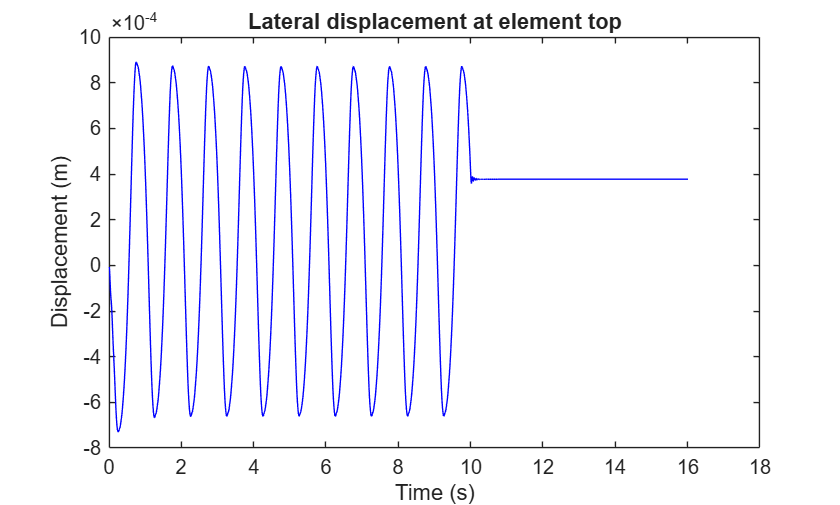

figure(2); clf;
%node 3 displacement relative to node 1
plot(d1(:,1),d1(:,5),'b');
title ('Lateral displacement at element top');
xlabel('Time (s)');
ylabel('Displacement (m)'); 

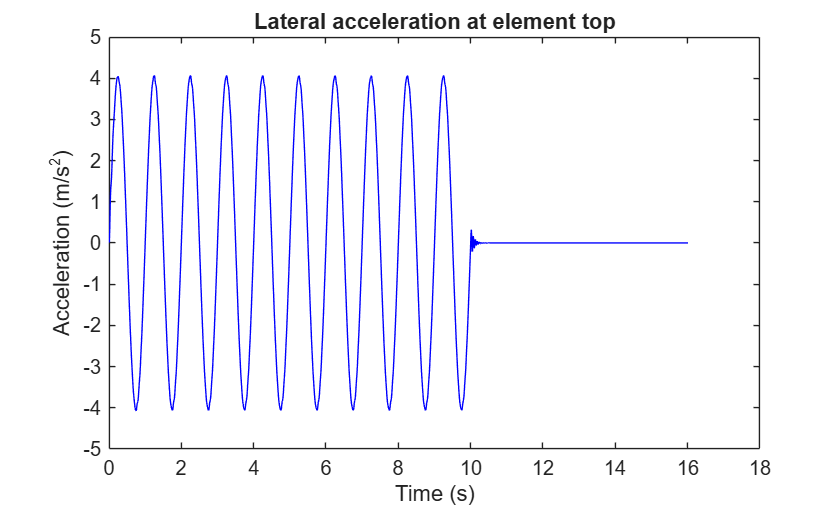

s=accMul*sin(0:pi/50:20*pi);
s=[s';zeros(1000,1)];
s1=interp1(0:0.01:20,s,a1(:,1));

figure(3); clf;
%node 3 acceleration
plot(a1(:,1),s1+a1(:,5),'b');
title ('Lateral acceleration at element top');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');